% Clear
clear
clc
close all

syms t s

%% 1. Second Order Underdamped System

G1_num = [1];
G1_den = [1 2 1];
G1 = tf(G1_num,G1_den)

G1 =
 
        1
  -------------
  s^2 + 2 s + 1
 
Continuous-time transfer function.
Model Properties


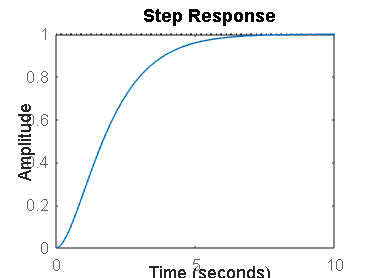

step(G1, 0.0:0.1:10)


%% 2. Second Order Overdamped System

G2_num = [1];
G2_denA = [1 2];
G2_denB = [1 3];
G2_den = conv(G2_denA,G2_denB)

G2_den =      1     5     6


G2 = tf(G2_num,G2_den)

G2 =
 
        1
  -------------
  s^2 + 5 s + 6
 
Continuous-time transfer function.
Model Properties


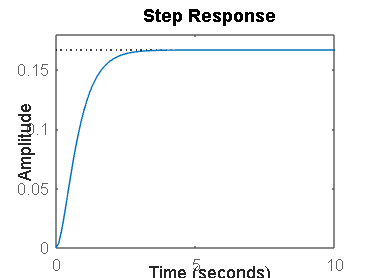

step(G2, 0.0:0.1:10)


%% 3. Second Order Critically Damped System

G3_num = [1];
G3_denA = [1 1];
G3_denB = [1 1];
G3_den = conv(G3_denA,G3_denB)

G3_den =      1     2     1


G3 = tf(G3_num,G3_den)

G3 =
 
        1
  -------------
  s^2 + 2 s + 1
 
Continuous-time transfer function.
Model Properties


step(G3, 0.0:0.1:10)


%% 4. First Order System

G4_num = [1];
G4_den = [1 1];
G4 = tf(G4_num,G4_den)

G4 =
 
    1
  -----
  s + 1
 
Continuous-time transfer function.
Model Properties


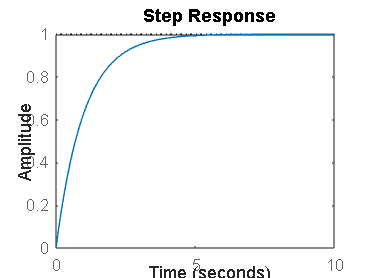

step(G4, 0.0:0.1:10)


%% 5. Resonant System

G5_num = [8 7 6 5 4 3 2];
G5_den = [1 2 3 4 5 6 7 1];
G5 = tf(G5_num,G5_den)

G5 =
 
     8 s^6 + 7 s^5 + 6 s^4 + 5 s^3 + 4 s^2 + 3 s + 2
  -----------------------------------------------------
  s^7 + 2 s^6 + 3 s^5 + 4 s^4 + 5 s^3 + 6 s^2 + 7 s + 1
 
Continuous-time transfer function.
Model Properties


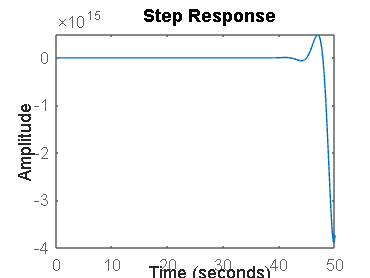

step(G5, 0:0.1:50)


%% 6. Electrical Filter with Multiple Poles

G6_num = [4 3 2 1];
G6_den = [1 2 3 4 1];
G6 = tf(G6_num,G6_den)

G6 =
 
     4 s^3 + 3 s^2 + 2 s + 1
  -----------------------------
  s^4 + 2 s^3 + 3 s^2 + 4 s + 1
 
Continuous-time transfer function.
Model Properties


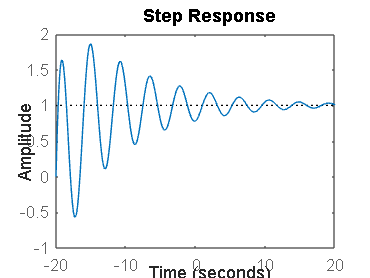

step(G6, -20:0.1:20)


%% 7. Plant with Time Delay

G7_num = [6 5 4 3 2];
G7_den = [1 2 3 4 5 1];
G7 = tf(G7_num,G7_den)

G7 =
 
     6 s^4 + 5 s^3 + 4 s^2 + 3 s + 2
  -------------------------------------
  s^5 + 2 s^4 + 3 s^3 + 4 s^2 + 5 s + 1
 
Continuous-time transfer function.
Model Properties


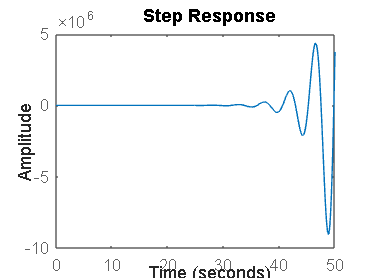

step(G7, 0:0.1:50)


%% 8. Nonlinear System Approximation

G8_num = [10 8 6 4 2];
G8_den = [1 3 5 7 9 1];
G8 = tf(G8_num,G8_den)

G8 =
 
    10 s^4 + 8 s^3 + 6 s^2 + 4 s + 2
  -------------------------------------
  s^5 + 3 s^4 + 5 s^3 + 7 s^2 + 9 s + 1
 
Continuous-time transfer function.
Model Properties


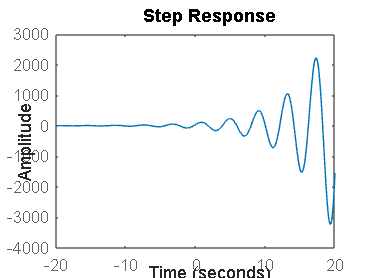

step(G8, -20:0.1:20)